# Exercise 11

## 1. YUV to RGB transformation

file_name = 'yuvdata.mat';
data = load(file_name);
lena = imread('lena.tiff');

data.rows*data.cols

ans = 230400

size(lena)

ans =    512   512     3


 data

data = struct with fields:
    cols: 640
    rows: 360
      yy: [230400×1 double]
      uu: [57600×1 double]
      vv: [57600×1 double]


a. Size of component yy (230 400) is equal to row*col (640*360)  while uu and vv component (57600) are not equal 

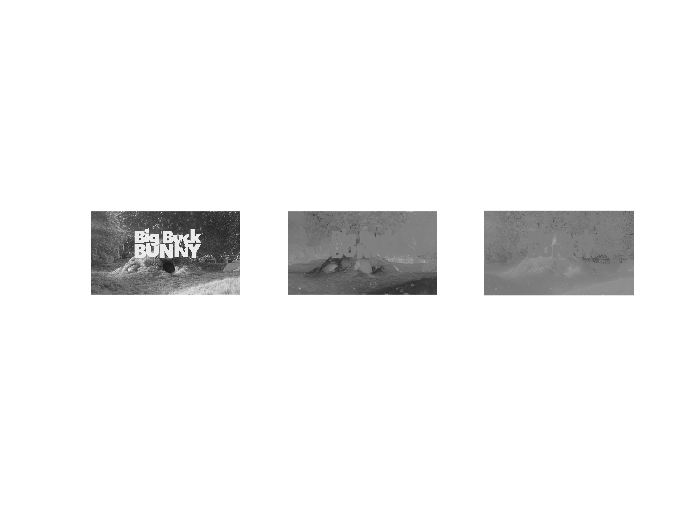

% data.uu
% data.yy
%doc reshape

Y = data.yy;
U = data.uu;
V = data.vv;

% Y = reshape(Y,360,640);
% U = reshape(U,180,320);
% V = reshape(V,180,320);

Y = reshape(Y,640,360);
U = reshape(U,320,180);
V = reshape(V,320,180);

U = imresize(U,640,360);
V = imresize(V,640,360);

figure,
subplot(1,3,1);
imshow(uint8(Y'));
subplot(1,3,2);
imshow(uint8(U'));
subplot(1,3,3);
imshow(uint8(V'));

% figure,
% subplot(1,3,1);
% imshow(uint8(Y));
% subplot(1,3,2);
% imshow(uint8(U));
% subplot(1,3,3);
% imshow(uint8(V));

%resize(lena,)
%reshape(data,640,)
%doc imresize

%c
U = U -127;
V = (V -127);
U

U =     -8    -9    -9    -7    -7    -8    -6    -6    -6    -6    -4    -4    -4    -6    -7    -8    -8    -9   -10   -11   -12   -12   -13   -13   -13   -15   -16   -18   -17   -18   -17   -17   -18   -17   -15   -16   -15   -14   -11    -8    -9   -10    -9    -9    -9   -10    -9   -10   -10    -9
    -9    -8    -8    -7    -5    -5    -8    -6    -7    -6    -5    -4    -5    -7    -7   -10   -11   -11   -12   -13   -12   -12   -13   -12   -12   -12   -11   -17   -18   -17   -17   -17   -17   -16   -15   -16   -15   -14   -11   -10    -9   -10    -9   -10   -10    -9   -10   -10    -9   -10
    -9    -8    -9    -8    -5    -3    -7    -7    -8    -7    -6    -5    -6    -8    -9   -10   -11   -11   -12   -12   -12   -11   -11   -11   -14   -11    -9   -16   -18   -18   -17   -15   -14   -12   -12   -14   -15   -14   -12   -10   -10   -10   -10    -9    -9    -9   -10    -9   -10    -9
    -6    -9    -9    -9    -6    -3    -5    -8    -8    -8    -7    -7    -7    -8    -8   

%d
YUV = cat(2,Y(:),U(:),V(:));

Error using cat
Dimensions of arrays being concatenated are not consistent.


%d
YuvToRgb = [1,0,1.402; 1,-0.34413,-0.71414; 1,1.772,0];
RGB = YuvToRgb*YUV';
R = reshape(RGB(1,:), [640, 360])';
G = reshape(RGB(2,:), [640, 360])';
B = reshape(RGB(3,:), [640, 360])';
RGB_map = cat(3, R, G, B);
%f

% What it means by reshaping to image size ?
%Y = reshape(Y,)

figure,imshow(uint8(RGB_map))

## 2. Chrominace subsampling

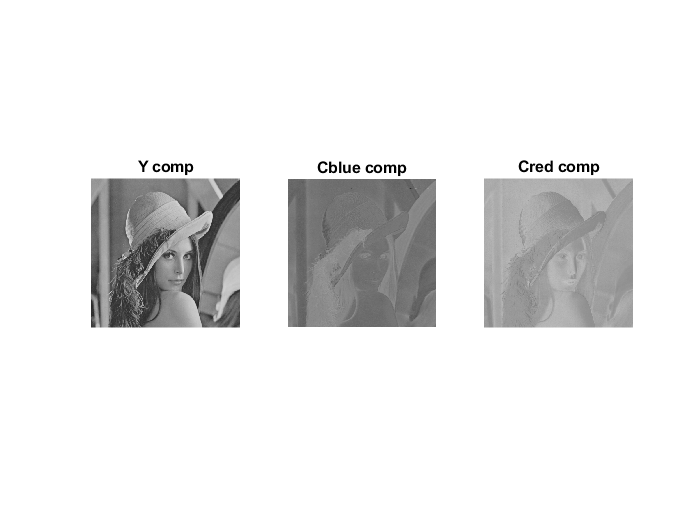

im = imread('lena.tiff');
im_ycbcr = rgb2ycbcr(im);
Y_2 = im_ycbcr(:,:,1);
Cb = im_ycbcr(:,:,2);
Cr = im_ycbcr(:,:,3);


figure,
subplot(1,3,1);
imshow(uint8(Y_2)); title('Y comp');
subplot(1,3,2);
imshow(uint8(Cb));title('Cblue comp');
subplot(1,3,3);
imshow(uint8(Cr));title('Cred comp');

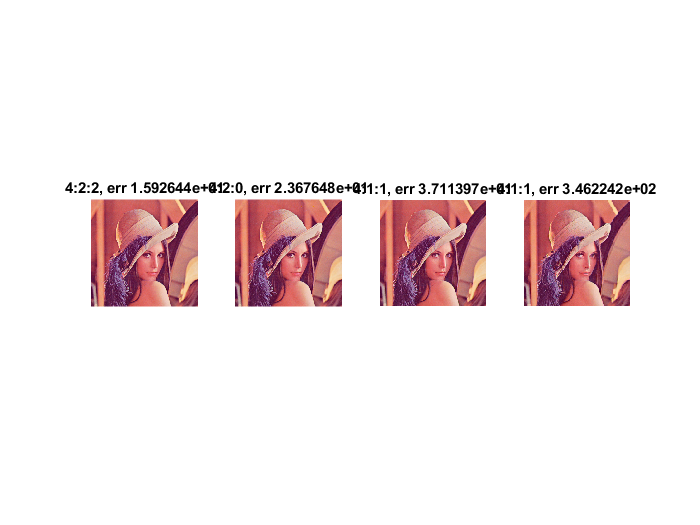



figure;
% To 4:2:2 have 1/2 horizontail resolution
% 
Cb_4_2_2 = Cb;
Cr_4_2_2 = Cr;
Cb_4_2_2=Cb_4_2_2(:,1:2:end);
Cr_4_2_2=Cr_4_2_2(:,1:2:end);
Ycbcrimg1 = cat(3, Y_2, repelem(Cb_4_2_2, 1, 2), repelem(Cr_4_2_2, 1, 2));
img1 = ycbcr2rgb(Ycbcrimg1);
%mean squared error
a1 = immse(im, img1);
subplot(1,4,1);
imshow(img1);title(sprintf('4:2:2, err %s',a1));



% To 4:2:0
% First row chroma copied it to second row chroma since
% its second row denote 0 chroma samples.
Cb_4_2_0 = Cb;
Cr_4_2_0 = Cr;

Cb_4_2_0 = Cb_4_2_0(1:2:end,1:2:end);
Cr_4_2_0 = Cr_4_2_0(1:2:end,1:2:end);

% 4:2:0 has 1/2 both 1/2 vertical and horizontal
% resolution
% Alternative : To 4:2:0 downsample by factor 0.5
%to get format 4:2:0. Unchange for Y component

% Cb_4_2_0_n = imresize(Cb,0.5)
% Cr_4_2_0_n = imresize(Cr,0.5)
Ycbcrimg2 = cat(3, Y_2, repelem(Cb_4_2_0, 2, 2), repelem(Cr_4_2_0, 2, 2));
img2 = ycbcr2rgb(Ycbcrimg2);
%mean squared error
a2 = immse(im, img2);
subplot(1,4,2);
imshow(img2);title(sprintf('4:2:0, err %s',a2))

%

%To 4:1:1
% 4:1:1 full vertical resolution but 1/4 horizontal
% resolution
Cb_4_1_1 = Cb;
Cr_4_1_1 = Cr;
Cb_4_1_1=Cb_4_1_1(:,1:4:end);
Cr_4_1_1=Cr_4_1_1(:,1:4:end);
Ycbcrimg1 = cat(3, Y_2, repelem(Cb_4_1_1, 1, 4), repelem(Cr_4_1_1, 1, 4));
img3 = ycbcr2rgb(Ycbcrimg1);
%mean squared error
a3 = immse(im, img3);
subplot(1,4,3);
imshow(img3);title(sprintf('4:1:1, err %s',a3))

%To 4:2:0
% downsample luminance only
% resolution
y = Y_2(1:4:end, 1:4:end);
Ycbcrimg4 = cat(3, repelem(y,4, 4), Cb, Cr);
img4 = ycbcr2rgb(Ycbcrimg4);
%mean squared error
a4 = immse(im, img4);
subplot(1,4,4);
imshow(img4);title(sprintf('Luminance , err %s',a4))